# Podstawy Automatykii II

# Jakub Szczypek, nr albumu 405912

# Ćwiczenie 12: Analiza nieliniowego systemu ll rezędu na plaszczyznie fazowej, l metoda Lapunova

# Poniedziałek: 13.06.2022 , godz: 17:00-18:30

**Cel ćwiczenia**

Celem ćwiczenia jest zapoznanie z analizą dynamiki systemów nieliniowych II rzęduopisanych w przestrzeni stanu z wykorzystaniem metody płaszczyzny fazowej, rozważanej wpoprzednim ćwiczeniu.

**Wstęp teoretyczny**

 W ćwiczeniu analizowana będzie stabilność nieliniowego systemu dynamicznego opisanego jednorodnym, nieliniowym równaniem różniczkowym II rzędu:

Równanie to opisuje np ruch ciężarka na sprężynie, gdzie x(t) to położenie ciężarka, w spółczynnik b opisuje rozpraszanie energii w układzie, współczynniki c oraz d opisują nieliniową sprężynę (d<0 sprężyna miękka, d>0 sprężyna twarda). W przypadku gdy współczynnik d =0 otrzymujemy znany z poprzedniego ćwiczenia układ liniowy. Jeżeli założymy, że zmiennymi stanu w tym układzie są:

położenie ciężarka **x(t) **oraz prędkość jegoruchu **v(t)**, to równanie może być zapisane w postaci równania stanu:

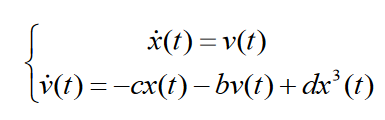

Układ nieliniowy z miękką sprężyną (d < 0) opisany przez wcześniejsze równania, posiada 3 punkty równowagi P1,2,3(x,v) o współrzędnych określonych przez położenie i prędkość (proszę zwrócić uwagę, że w położeniu równowagi prędkość musi być równa zero!) : 

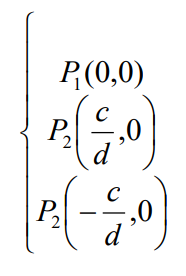

Można udowodnić, że punkt P1 jest punktem asymptotycznie stabilnym, a punkty P2,3 są punktami niestabilnymi. Analityczne wyznaczenie obszaru „atrakcji” (obszaru „przyciągania asymptotycznego”) jest zagadnieniem trudnym. Przybliżone wyznaczenie tego obszaru jest możliwe z wykorzystaniem modelowania w środowisku MATLAB/SIMULINK, co będzie należało zrobić w trakcie dalszej części ćwiczenia. 

**Realizacja ćwiczenia**

Stworzony schemat blokowy w simulinku  w simulinku, który był umieszczony w instrukcji zadania:

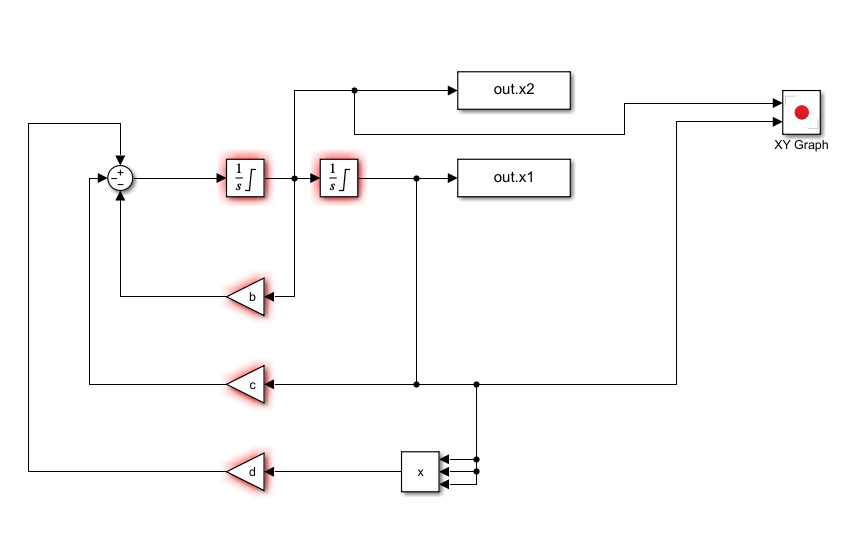

Podczas wykonywania ćwiczenia posłużyłem się poniższym skryptem w MATLABIE:

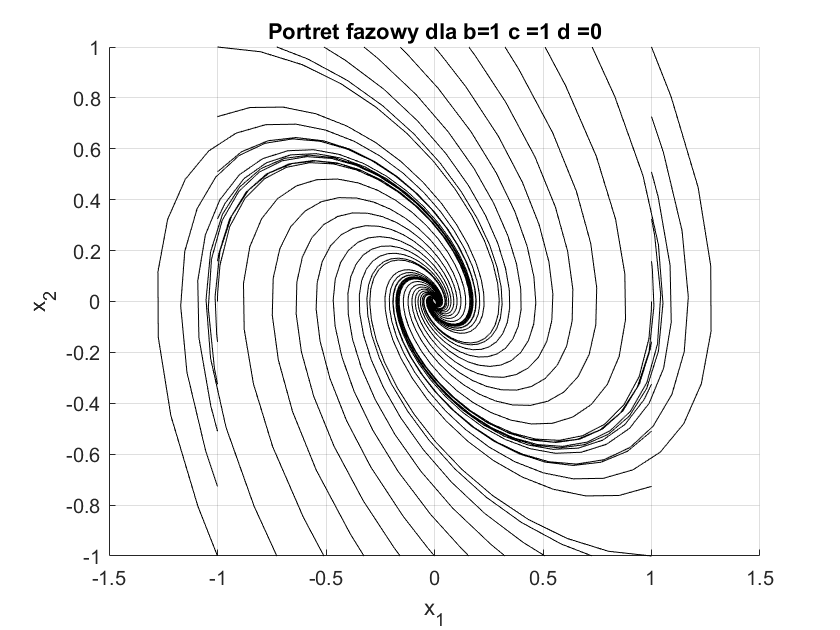

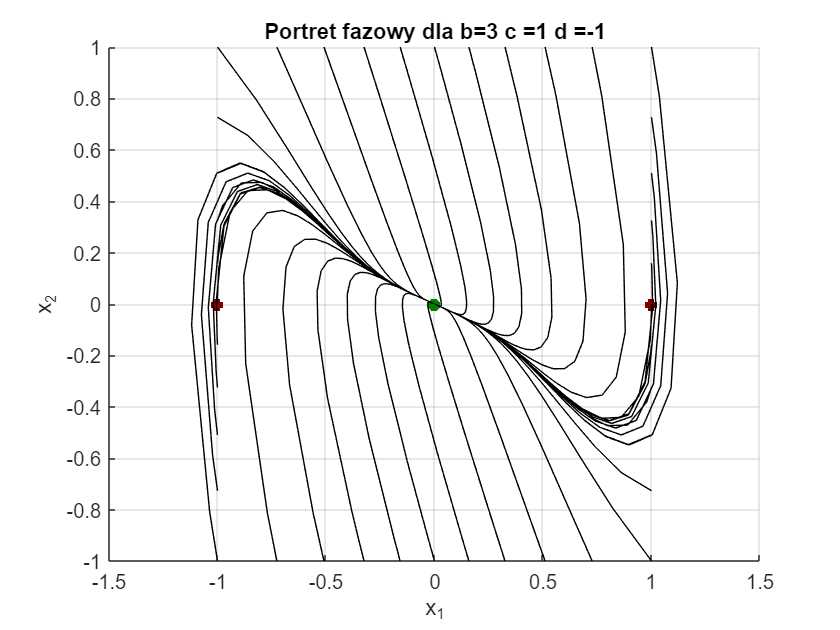

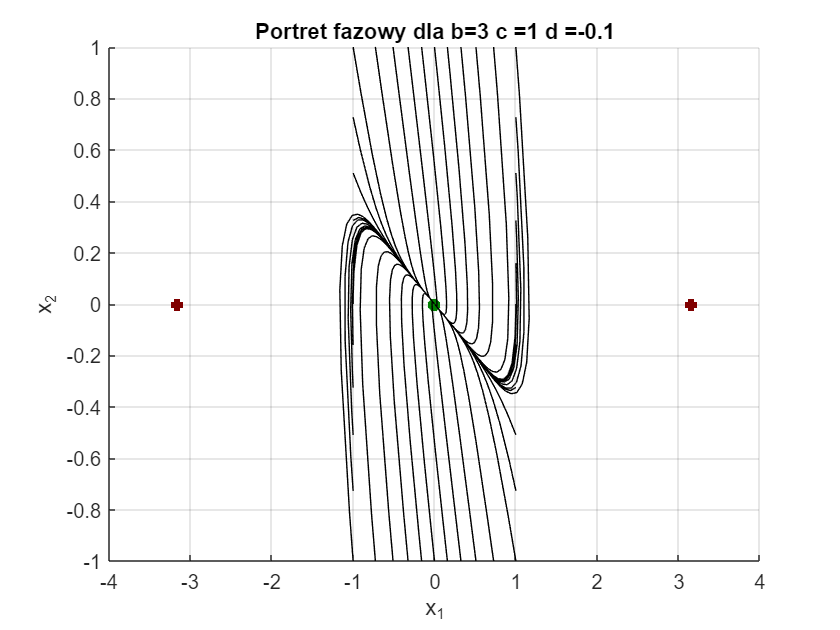

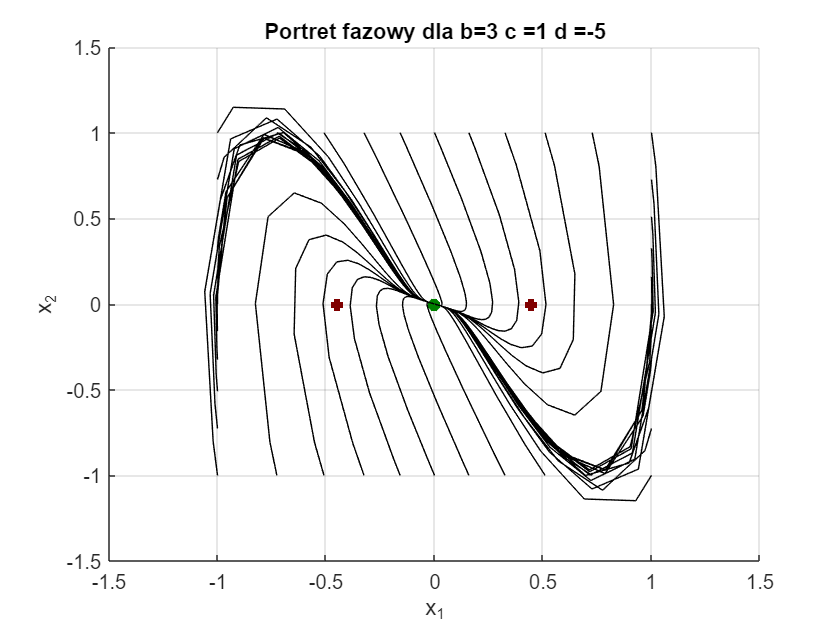

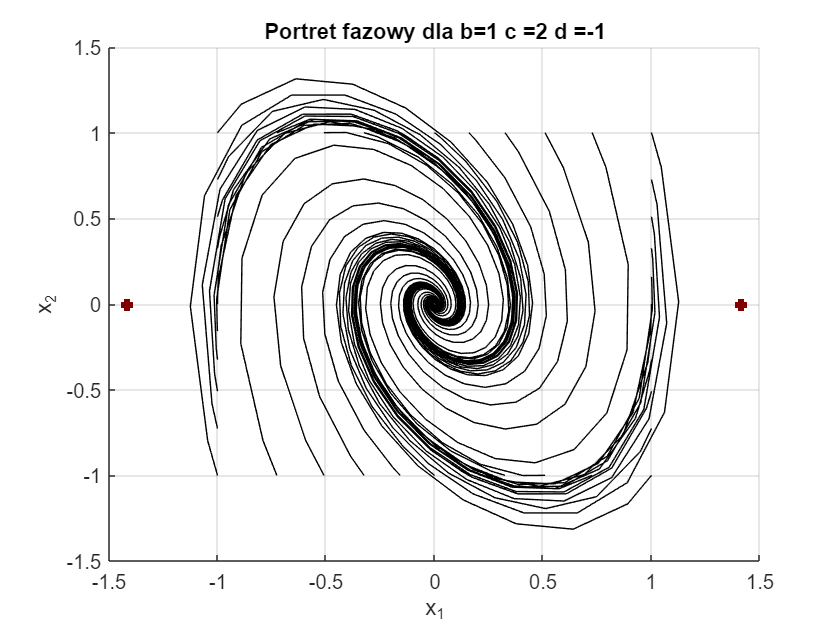

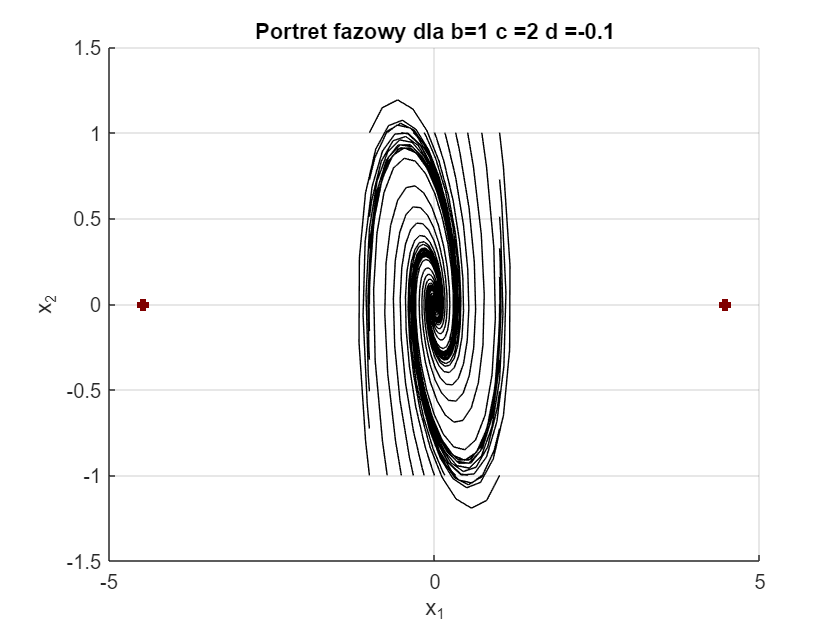

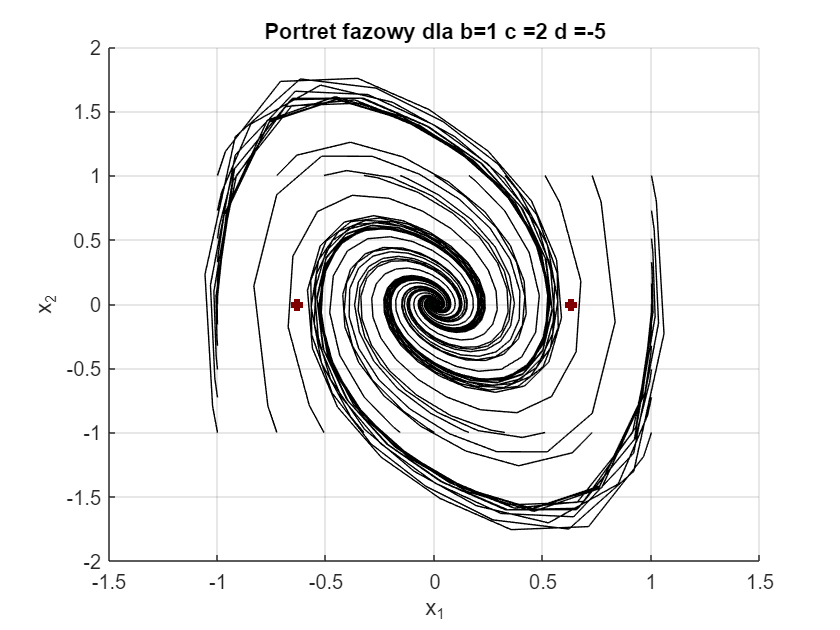

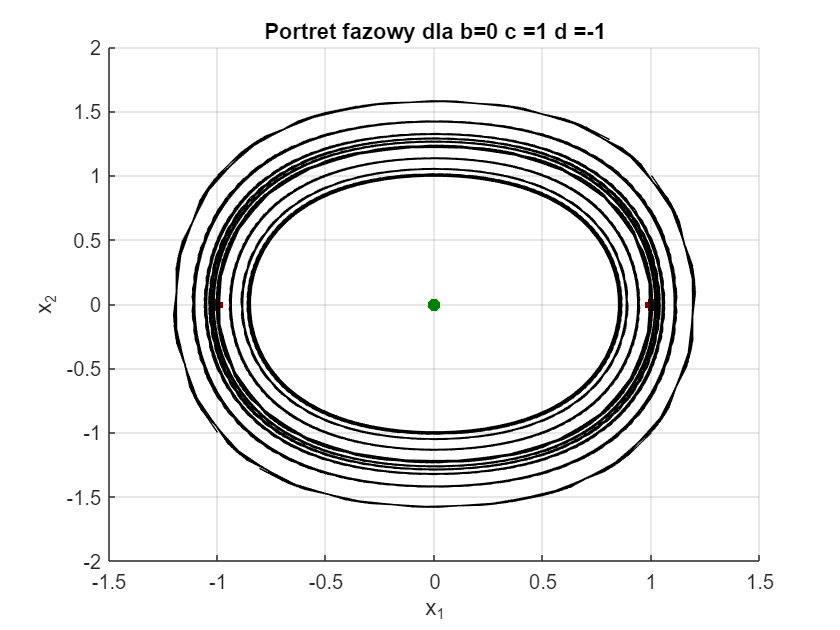

%Skrypt podobny do skryptu z cwiczenia dot układów liniowych, ale adaptowany do analizy stabilności
%z wykorzystaniem 1 metody Lapunova:
%Poniżej wpsiujemy parametry:
%parametry b, c>0:
%parametr d<0,
% |c|<|d|

B = [1, 3, 3, 3, 1, 1, 1, 0, 0.1];
C = [1, 1, 1, 1, 2, 2, 2, 1, 2];
D = [0, -1, -0.1, -5 -1, -0.1, -5, -1, -1];

for i=1:9
    b=B(i); %b>2sqrt(c) żeby układ liniowy (d=0) był aperiodyczny
    c=C(i);
    d=D(i); %współcznynnik częsci nieliniowej wg równania z instrukcji. Powinien być < 0
    T=10; %końcowy czas symulacji
    P=20; %ilość warunków początkowych do testu. Mniejsza ilość daje lepszą czytelność, ale większa ilość
    % pozwala dokładniej oszacować obszar przyciągania asymptotycznego.
    %pusty wykres:
    figure;
    hold on; 
    grid on;
    %wrysowanie punktow równowagi na wykresie:
    if d<0
        %punkty niestabilne:
        plot(sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);
        plot(-sqrt(-c/d),0,'+','linewidth',3,'color',[.5 0 0]);
        %punkt stabilny:
        plot(0,0,'*','linewidth',3,'color',[0 .5 0]);
end;
    %Wyznaczanie zbioru warunków poczatkowych obejmujących całą pł. fazową:
    a=0:(pi/P):(2*pi);
    X1=[cos(a);sin(a)];
    X2=X1./[max(abs(X1));max(abs(X1))];
    %
    M=size(X2,2);
    for m=1:M
    x0=X2(:,m);
    %tu wpisujemy nazwę funkcji z modelem układu n-l:
    out = sim('met_Lap_1_31', T);
    plot(out.x1, out.x2,'k-');
    str = strcat('Portret fazowy dla b= ', num2str(b), ' c = ', num2str(c), ' d =', num2str(d));
    title(str)
    xlabel('x_1');
    ylabel('x_2');
end;
end;

**Wnioski**

Wykonane ćwiczenie pozwoliło zapoznać się z analizą nieliniowych systemów II rzędu na płaszczyźnie fazowej za pomocą pierwszej metody Lapunova. Ćwiczenie zostało zrealizowane za pomocą środowiska Matlab i Simulink. Z otrzymanych wykresów dla kolejnych zestawów parametrów można było zaobserwować z jakiego rodzaju układami mieliśmy do czynienia. Pierwszy układ to układ liniowy, czyli taki jak rozważane w poprzednim tygodniu, wynika to z tego że wartość współczynnika d była równa zero. Kolejne układy były układami stabilnymi asymptotycznie. Ich wykresy dążą do początku układu współrzędnych. Dwa ostatnie układy to układy niestabilne asymptotycznie, ponieważ ich przebiegi były w okolicy punktu (0, 0), ale nigdy ich nie osiągały.